Demo code for Figure 3 of Idesis (2022) - Edge centric analysis of stroke patients. An alternative approach for biomarkers of lesion recovery

Edge-centric code adapted from Faskowitz, J. et al (2020) and Zamani Esfahalani (2020)

(https://github.com/brain-networks)

Adapted by: Sebastian Idesis - sebastian.idesis@upf.edu (Feb 2022)

Initialize script

clear all;close all;clc; %Close everything
nodes = 200; % Amount of nodes from the dataset

Add helper functions and data to path

addpath('Functions');
addpath('Data');
addpath('Functions\Violinplot-Matlab-master');
addpath('Functions\cbrewer');

Load regional time series

load data/ts.mat %Demo data (Taken from https://www.brainnetworkslab.com/coderesources)
load('hcp200.mat') %Demo data (Taken from https://www.brainnetworkslab.com/coderesources)

Create fake data of other 4 control subjects

amount_of_controls= 5; %Number for control subjects for demo
for subj = 1:amount_of_controls
    ts_controls(:,:,subj)= ts.*(randn(1200,200)); %original ts plus a small factor random amount to make every subject different
end

Create fake data of 5 stroke patients

amount_of_patients= 5; %Number for demo
for subj = 1:amount_of_patients
    ts_patients(:,:,subj)= ts.*(randn(1200,200)*4); %original ts plus a bigger factor random amount to make every subject different
end

Load data for entropy calculation - Controls

ts_controls_entropy=[]; % initialize variable
for subj = 1:amount_of_patients 
    ts_toload_controls = zscore(ts_controls(:,:,subj)); %z-score time series of each subject
    ts_controls_entropy = [ts_controls_entropy ts_toload_controls'];  %accumulate all the time series for next analysis
end

Load data for entropy calculation - Patients

ts_patients_entropy=[]; % initialize variable
for subj = 1:amount_of_patients 
    ts_toload_patients = zscore(ts_patients(:,:,subj)); %z-score time series of each subject
    ts_patients_entropy = [ts_patients_entropy ts_toload_patients'];  %accumulate all the time series for next analysis
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%ENTROPY CALCULATION %%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Entropy calculation - Controls

% create edge time series from regional time series
ts_controls_entropy = ts_controls_entropy';
[T_controls,N_controls] = size(ts_controls_entropy);
M_controls = N_controls*(N_controls - 1)/2; 
ets_controls = fcn_edgets(ts_controls_entropy,1); % this step does the z-scoring and element-wise products. the output is a [time x edge] matrix.
% run kmeans -- note that in principle any clustering algorithm can be
% applied to edge time series or the efc matrix
k = 10; 
ci_controls= kmeans(ets_controls',k,...
    'distance','sqeuclidean',...
    'maxiter',1000);
% map edge communities into matrix
mat_controls = zeros(N_controls);
mat_controls(triu(ones(N_controls),1) > 0) = ci_controls; % this step gives you the indices of each edge
mat_controls = mat_controls + mat_controls';

%% calculate normalized entropy
[u_controls,v_controls] = find(triu(ones(N_controls),1)); % this step gives you the indices of each edge
[~,enorm_controls] = fcn_node_entropy(ci_controls,u_controls,v_controls,N_controls);

Entropy calculation - Patients

% create edge time series from regional time series
ts_patients_entropy = ts_patients_entropy';
[T_patients,N_patients] = size(ts_patients_entropy);
M_patients = N_patients*(N_patients - 1)/2; 
ets_patients = fcn_edgets(ts_patients_entropy,1); % this step does the z-scoring and element-wise products. the output is a [time x edge] matrix.
% run kmeans -- note that in principle any clustering algorithm can be
% applied to edge time series or the efc matrix
k = 10; 
ci_patients= kmeans(ets_patients',k,...
    'distance','sqeuclidean',...
    'maxiter',1000);
% map edge communities into matrix
mat_patients = zeros(N_patients);
mat_patients(triu(ones(N_patients),1) > 0) = ci_patients; % this step gives you the indices of each edge
mat_patients = mat_patients + mat_patients';

%% calculate normalized entropy
[u_patients,v_patients] = find(triu(ones(N_patients),1)); % this step gives you the indices of each edge
[~,enorm_patients] = fcn_node_entropy(ci_patients,u_patients,v_patients,N_patients);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%Visualization%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Replicate 2nd and 3rd variables with calculation from the corresponding time points

Entropy across time

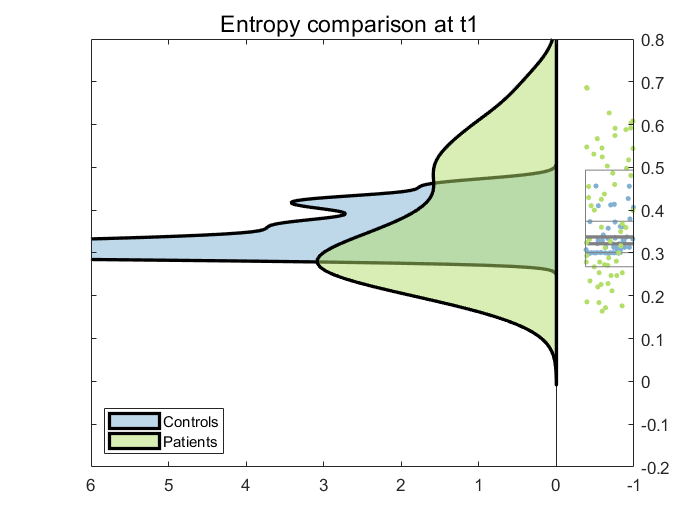

figure();
[cb] = cbrewer('qual','Set3',10,'pchip'); %Load color pallete 
[h1, u1] = raincloud_plot(enorm_controls, cb(5,:), ...
    'box_on', 1,'box_dodge', 1,'box_dodge_amount',.1, 'dot_dodge_amount', .1, 'alpha', 0.5); %Raincloud properties
hold on
[h2, u2] = raincloud_plot(enorm_patients, cb(7,:),...
    'box_on', 1,'box_dodge', 1,'box_dodge_amount',.1, 'dot_dodge_amount', .1, 'alpha', 0.5);%Raincloud properties

% Defining colors and borders properties
set(h1{3}, 'FaceColor','none','EdgeColor',[0.5 0.5 0.5])
set(h1{4}, 'col',[0.5 0.5 0.5]); set(h1{5}, 'col',[0.5 0.5 0.5]);set(h1{6}, 'col',[0.5 0.5 0.5]);set(h1{3}, 'LineWidth', 0.5);

set(h2{3}, 'FaceColor','none','EdgeColor',[0.5 0.5 0.5])
set(h2{4}, 'col',[0.5 0.5 0.5]);set(h2{5}, 'col',[0.5 0.5 0.5]);set(h2{6}, 'col',[0.5 0.5 0.5]); set(h2{3}, 'LineWidth', 0.1);

xlim([-.2 .8]);ylim([-1 6]);camroll(90)
sgtitle('Entropy comparison at t1');legend([h1{1} h2{1}],{'Controls','Patients'},'Location','southwest')

Entropy across time within system

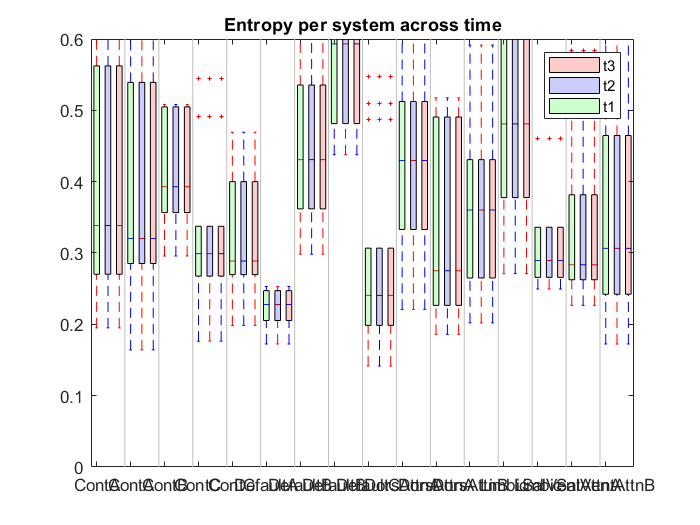

figure()
enorm_combined = vertcat(enorm_patients,enorm_patients,enorm_patients); % Combine the 3 time points vectors (Replace the 2nd and 3rd for the corresponding data)
group_enorm = repelem([{'t1'},{'t2'},{'t3'}],[200 200 200])'; % group assignment for each data point
lab_combined = repmat(lab,3);lab_combined = lab_combined(:,1); % labels configuration
net2 = repelem([net],[3]); % labels configuration

h= boxplot(enorm_combined, ...
    {lab_combined,group_enorm}, ... 
    'Notch','off', ...
    'Labels',net2, ...
    'OutlierSize',2, ...
    'Colors','rb', ...
    'FactorSeparator',1);


color = ['r','b','g','r','b','g','r','b','g','r','b','g','r','b','g','r','b','g','r','b'...
    ,'g','r','b','g','r','b','g','r','b','g','r','b','g','r','b','g','r','b','g','r','b','g','r','b','g','r','b','g']; %Filling colors (If needed, only one could be changed for emphasis)
c = findobj(gca,'Tag','Box');
for j=1:length(c)
    patch(get(c(j),'XData'),get(c(j),'YData'),color(j),'FaceAlpha',.2);
end
clear xt; clear yt;
yt = get(gca, 'YTick'); axis([xlim    0 0.6])
xt = get(gca, 'XTick'); net3=net2(1:2:33);
xticks([1:3:66]);set(gca,'XtickLabel',net3)

boxes = findobj(gca, 'Tag', 'Box');legend('t3','t2','t1'); title ('Entropy per system across time')

Upper triangle FC

%% Replicate 2nd and 3rd variables with calculation from the corresponding time points

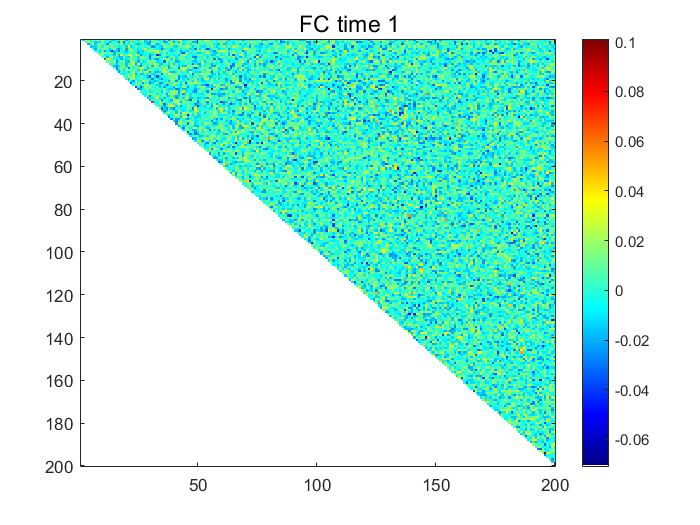

amount_of_patients=5;
nodes_per_subject=zeros(size(ts_patients,2),size(ts_patients,2),amount_of_patients);
for subj = 1:amount_of_patients
   temp_test_matrix = ts_patients(:,:,subj) ; % Time series of each subject
   test_matrix = corrcoef(temp_test_matrix);  % Matrix of each subject
   nodes_per_subject(:,:,subj) = test_matrix; %Accumulation of matrices 
end

t1_avg_fc = nanmean(nodes_per_subject,3); % Average of all subjects' matrices
t1_avg_fc_z = zscore(t1_avg_fc); % z-scored the averaged FC

figure()
Alo = tril(t1_avg_fc); %Get upper triangle
Alo(Alo>0)=1; %Mask
Alo(Alo<0)=1; %Mask
t1_avg_fc(Alo==1) = nan; %Mask
myColorMap = jet(256);
myColorMap(1,:) = 1;
colormap(myColorMap);
caxis([-1 1])

imagesc(t1_avg_fc);
sgtitle('FC time 1') %Replicate with time 2 and 3 data
colorbar()


load('data_for_circulargraph.mat')
network_direccionality_avg_z_t1_thresholded = network_direccionality_avg_z_t1; %Copy of the network connections matrix
network_direccionality_avg_z_t1_thresholded(abs(network_direccionality_avg_z_t1)<1.75)=0; %Mask (1.75 could be modified to emphasize less or more the connections)
figure()
colors_circle = cbrewer('div', 'RdBu', 20);

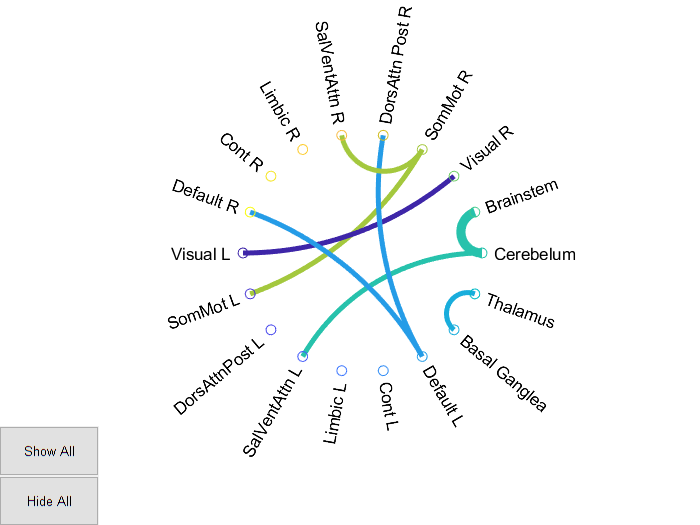

temp=abs(round(network_direccionality_avg_z_t1_thresholded)); %round values to improve visualization
myColorMap = lines(length(temp));
myLabel={'Visual L','SomMot L','DorsAttnPost L','SalVentAttn L','Limbic L','Cont L',...
    'Default L','Basal Ganglea','Thalamus','Cerebelum','Brainstem',...
    'Visual R','SomMot R','DorsAttn Post R','SalVentAttn R','Limbic R',...
    'Cont R','Default R'};
circularGraph(temp,'Label',myLabel);
title('T1')